# Task 1 in Hands-On AI for Smart Appliances Workshop

## **1. Data from rotating machinery collected using sensors**

Rotating machinery, such as gears, bearings, and motors, forms the backbone of many home appliances. By leveraging physics-based features that analyze rotation rates and machine harmonics, we can monitor the health of these components in real time. This approach enables the detection and isolation of specific hardware degradation and faults, allowing appliances to operate more efficiently, predict maintenance needs, and extend their operational lifespan. 

Machinery Failure Prevention Technology (MFPT) Challenge Data (Full dataset available at: [GitHub - mathworks/RollingElementBearingFaultDiagnosis-Data: Data set for Rolling Element Bearing Fault Diagnosis example in Predictive Maintenance Toolbox](https://github.com/mathworks/RollingElementBearingFaultDiagnosis-Data)) contains 23 data sets collected from machines under various fault conditions. For example, localized faults in a rolling element bearing may occur in the outer race, the inner race, the cage, or a rolling element. High frequency resonances between the bearing and the response transducer are excited when the rolling elements strike a local fault on the outer or inner race, or a fault on a rolling element strikes the outer or inner race. The following picture shows a rolling element striking a local fault at the inner race. 

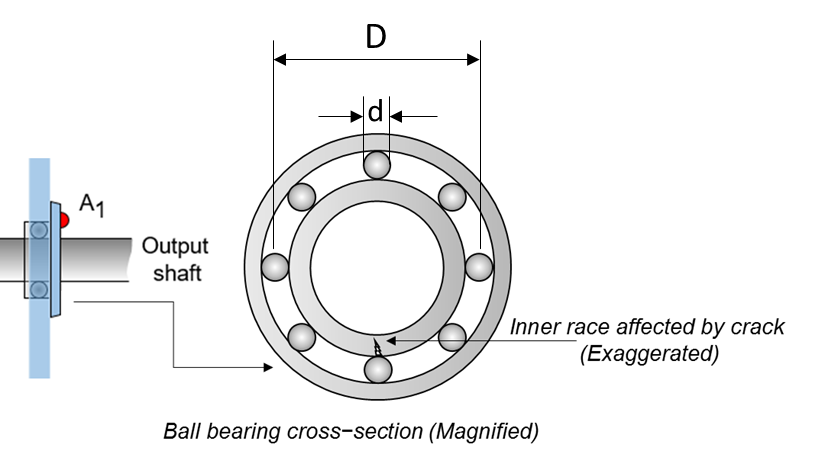

In task 1, we select 20 data sets collected from a bearing test rig, with 3 under normal conditions, 3 with outer race faults under constant load, 7 with outer race faults under various loads, and 7 with inner race faults under various loads. The data in the stored tables are windowed as arrays of 5000 data points each.

load("valTable.mat")
load("trainTable.mat")
load("testTable.mat")
plotRawData(trainTable)

## **2. Feature Extraction **

You can use the Diagnostic Feature Designer (DFD) App from Predictive Maintenance Toolbox to extract and select feature for building anomaly detection and fault diagnosis models. The DFD App can help you explore features and generate function to extract those features. The App can help you extract basic time domain and frequency domain features even you do not have any prior knowldge of bearings.

Here, we have already generated the function diagnosticFeatures to extract features. You car run the script below to extract features for the training and testing data.

feaTest = diagnosticFeatures(testTable);
feaTrain = diagnosticFeatures(trainTable)

Once the feature table is generated, you can save it for the upcoming exercises. 

save features.mat feaTrain feaTest 

Refer to [Rolling Element Bearing Fault Diagnosis - MATLAB & Simulink](https://www.mathworks.com/help/predmaint/ug/Rolling-Element-Bearing-Fault-Diagnosis.html) for more techniques for extracting features for bearing fault diagnosis.

## **3. Try Feature Extraction Exploration in **Diagnostic Feature Designer** App**

You can follow the instructions and explore the features. You can generate the feature extraction functions in the DFD App. 

(1) Launch the DFD App: 

diagnosticFeatureDesigner

(2) Click **New Session** in the FILE tab. 

- Choose valTable (your validation data from workspace) in Source. 

- Check Time and gs under data

- Uncheck load and fileName since we do not need them for this task. Note, you should specify label as Condition Variable in the Variable Type as we are using it as labels for the future modeling.

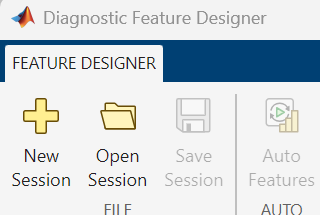

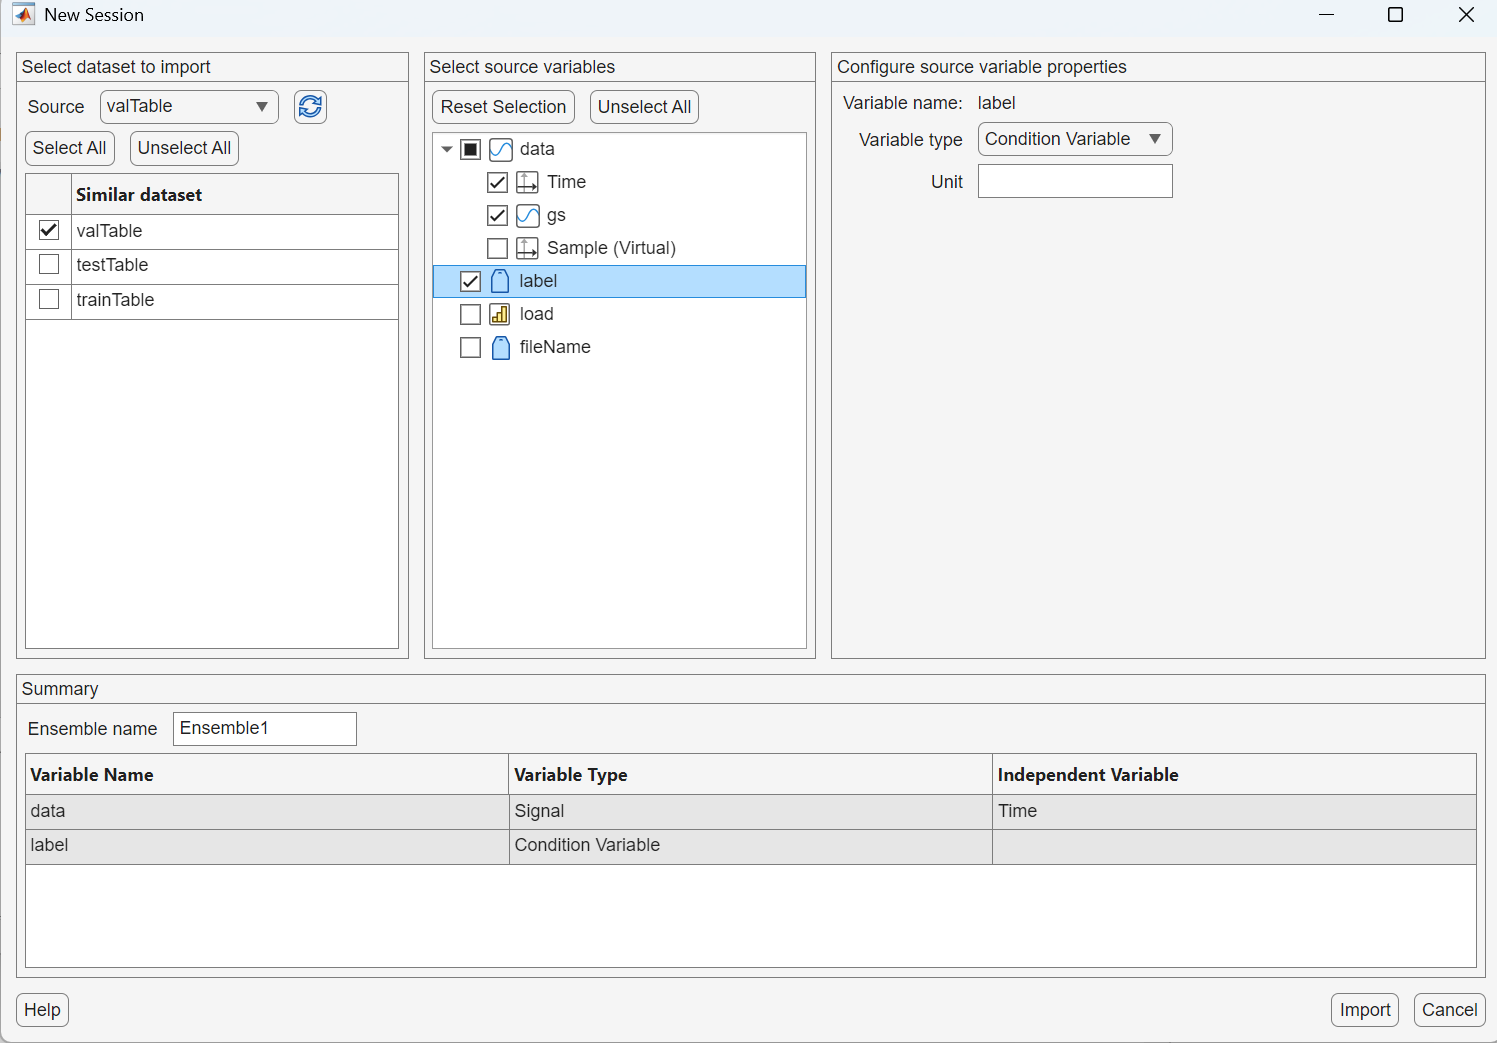

(3) Perform spectrum analysis for the data. 

- Select gs and click Welch's Method in Spectral Estimation. The reason of performing spectrum analysis here is we believe most of the features related to bearing fault is easier to be observed in the frequency domain. 

- Click Apply when WELCH'S METHOD tab shows. Since we only have 27 samples in the loaded validation data, the process should be fairly fast. 

- If you load training dataset, this process would take longer time. We suggest you start the analyzing process with a small portion of your entire dataset. 

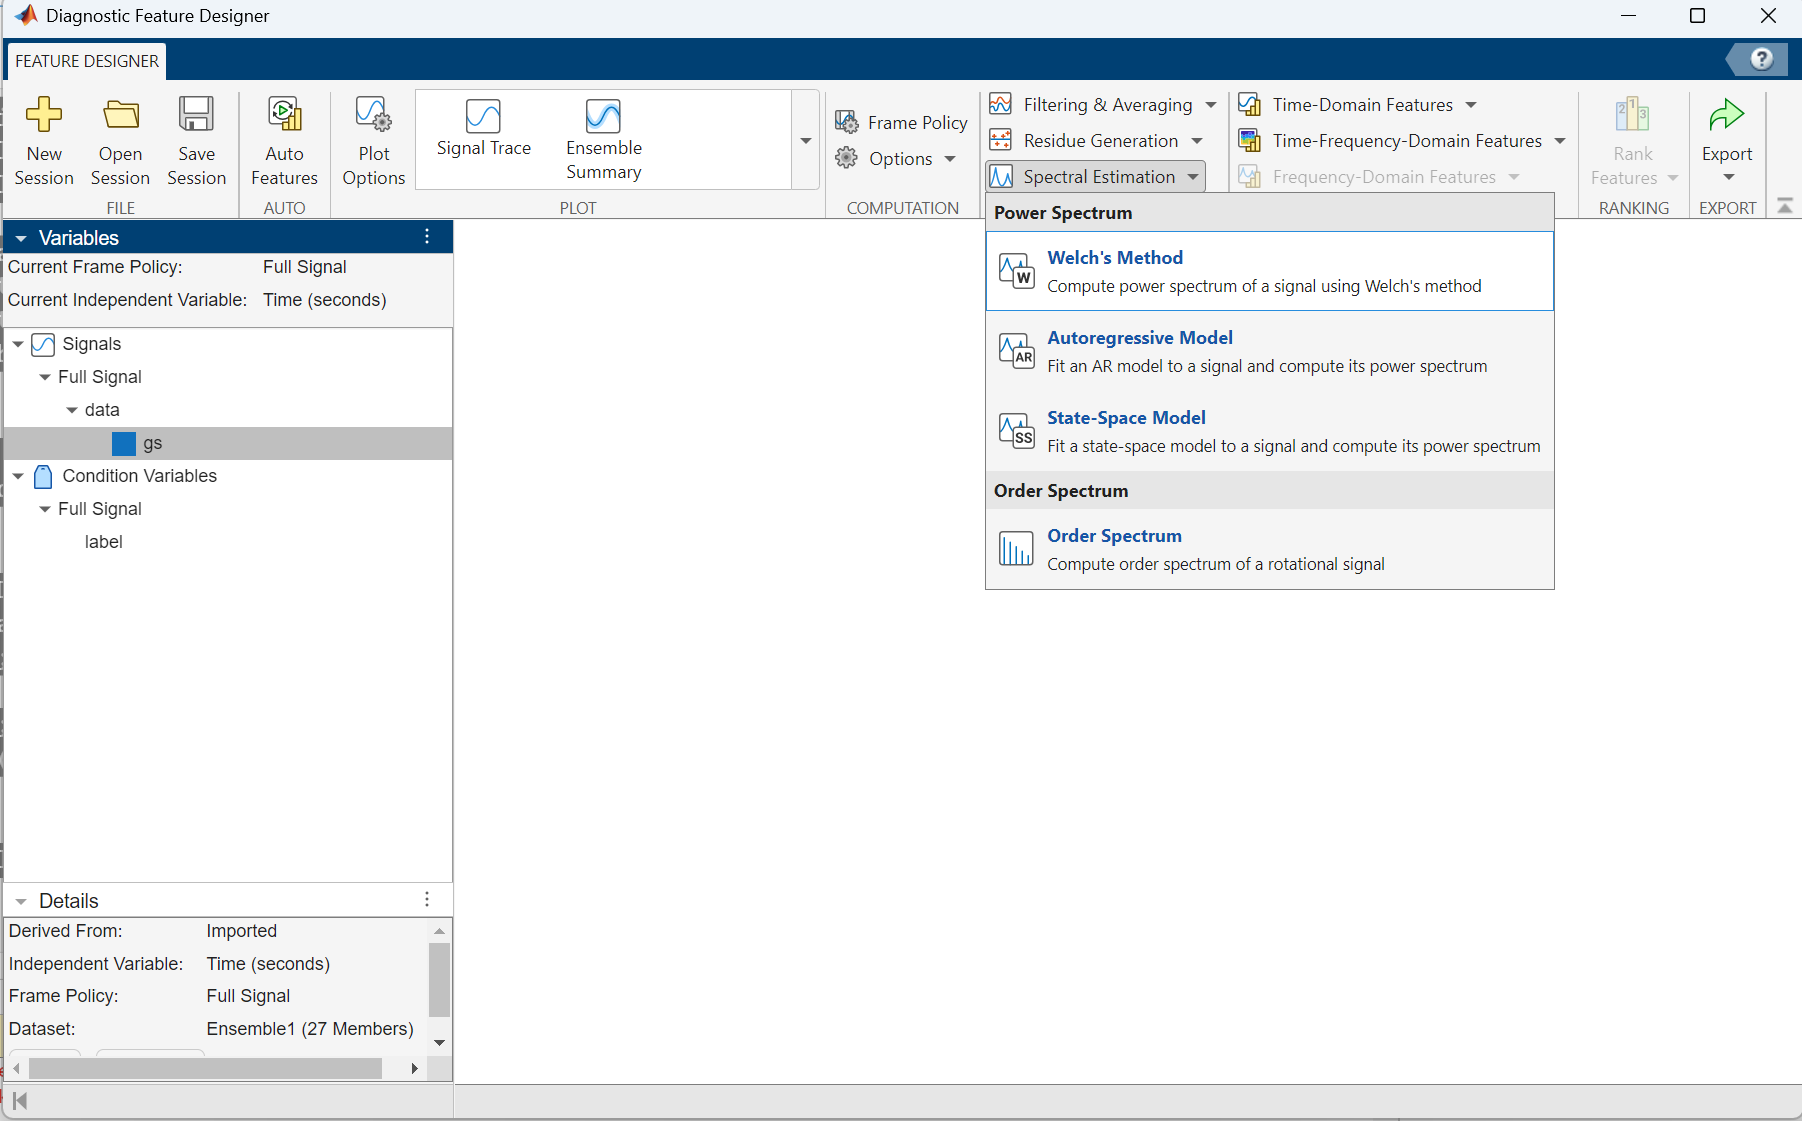

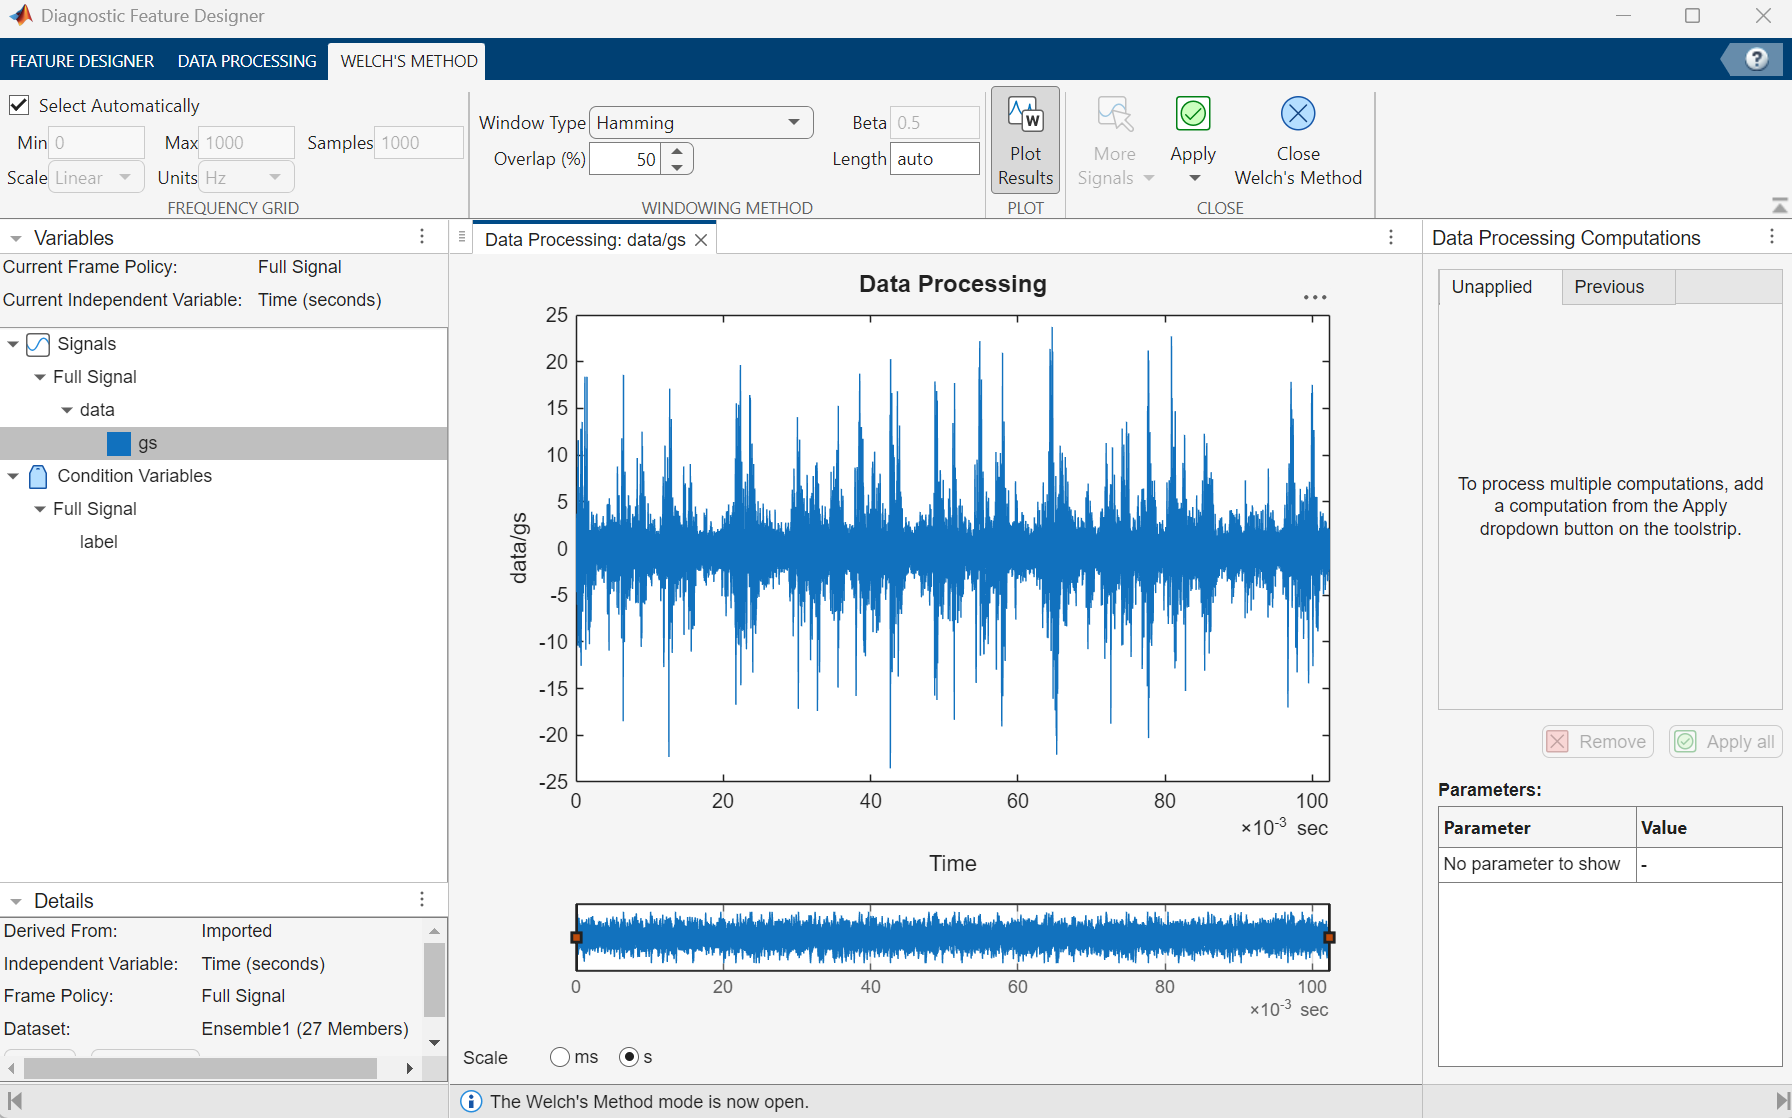

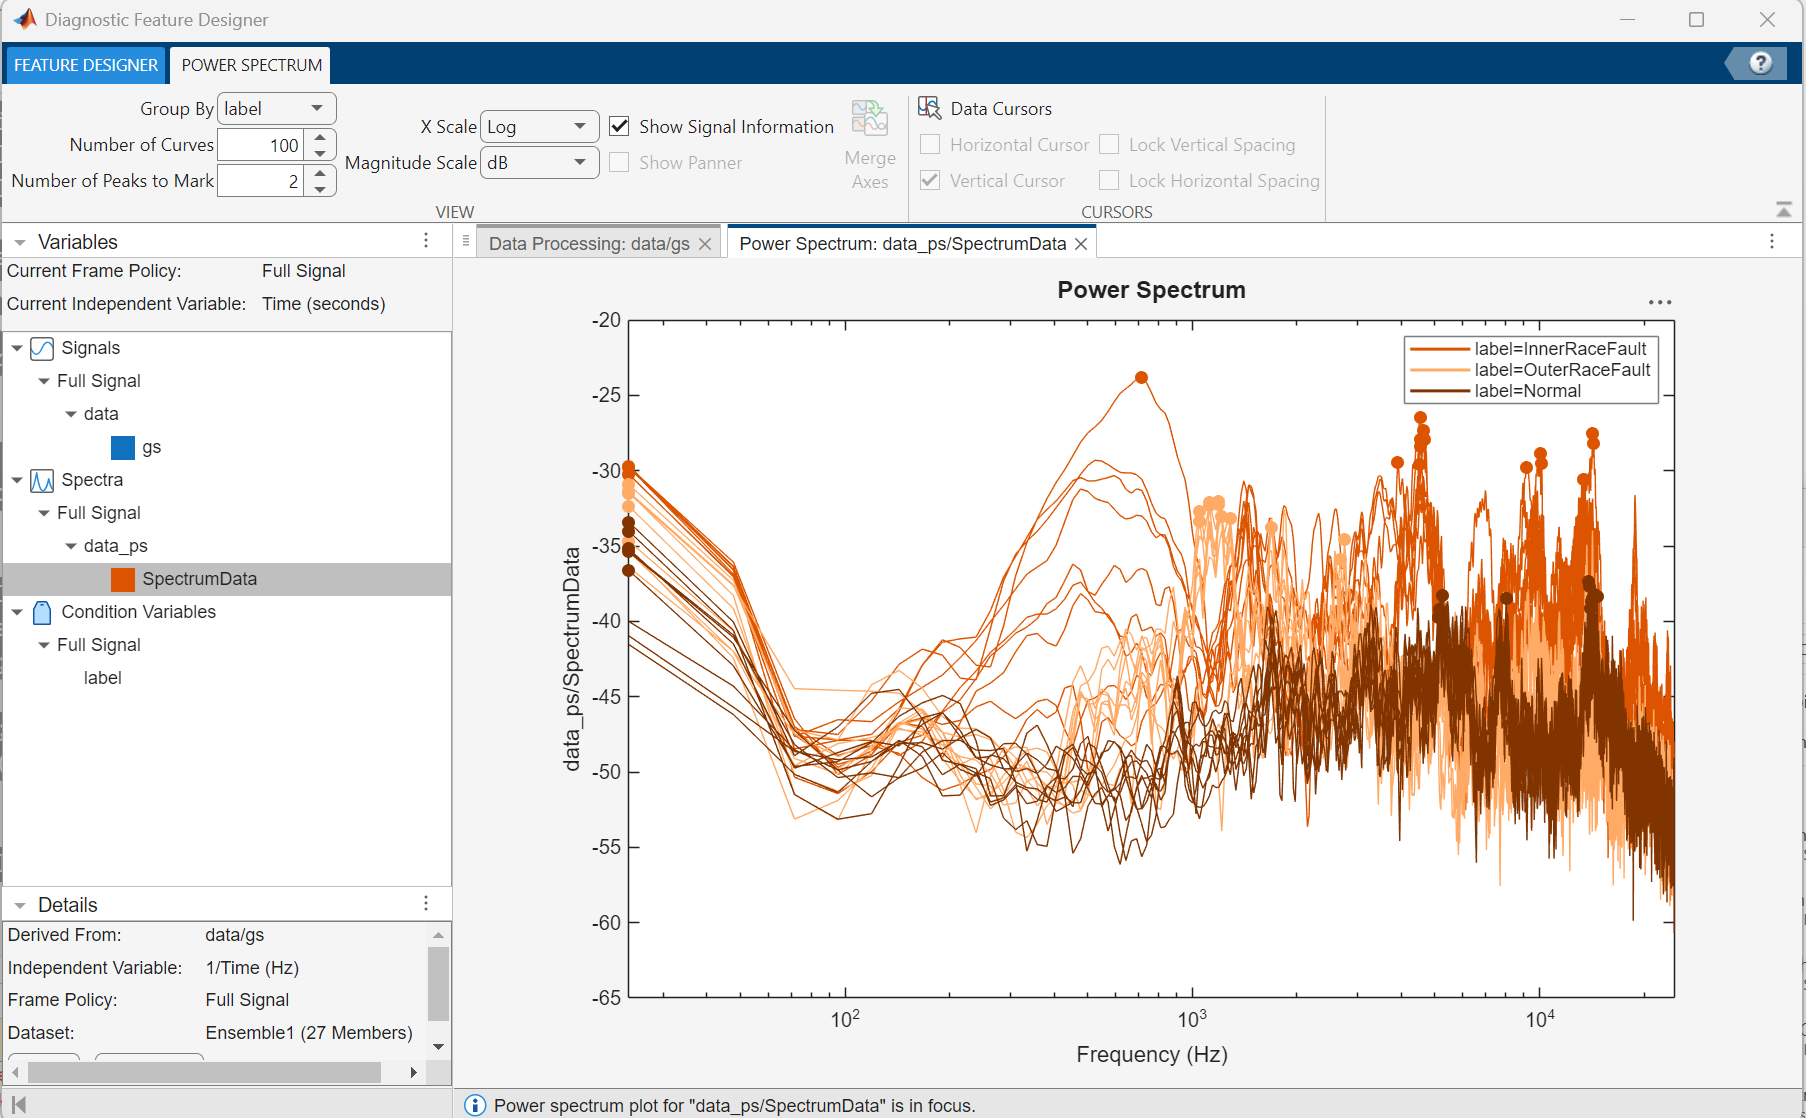

(4) Extract Spectral Features from the calculated spectrum. 

- Click the SpectrumData. 

- Switch to the FEATURE DESIGNER tab and click the Spectral Features in Frequency-Domain Features. 

- You can directly choose Bearing Faults Features if you have additional information about the basic parameters of the bearing and the operation conditions. 

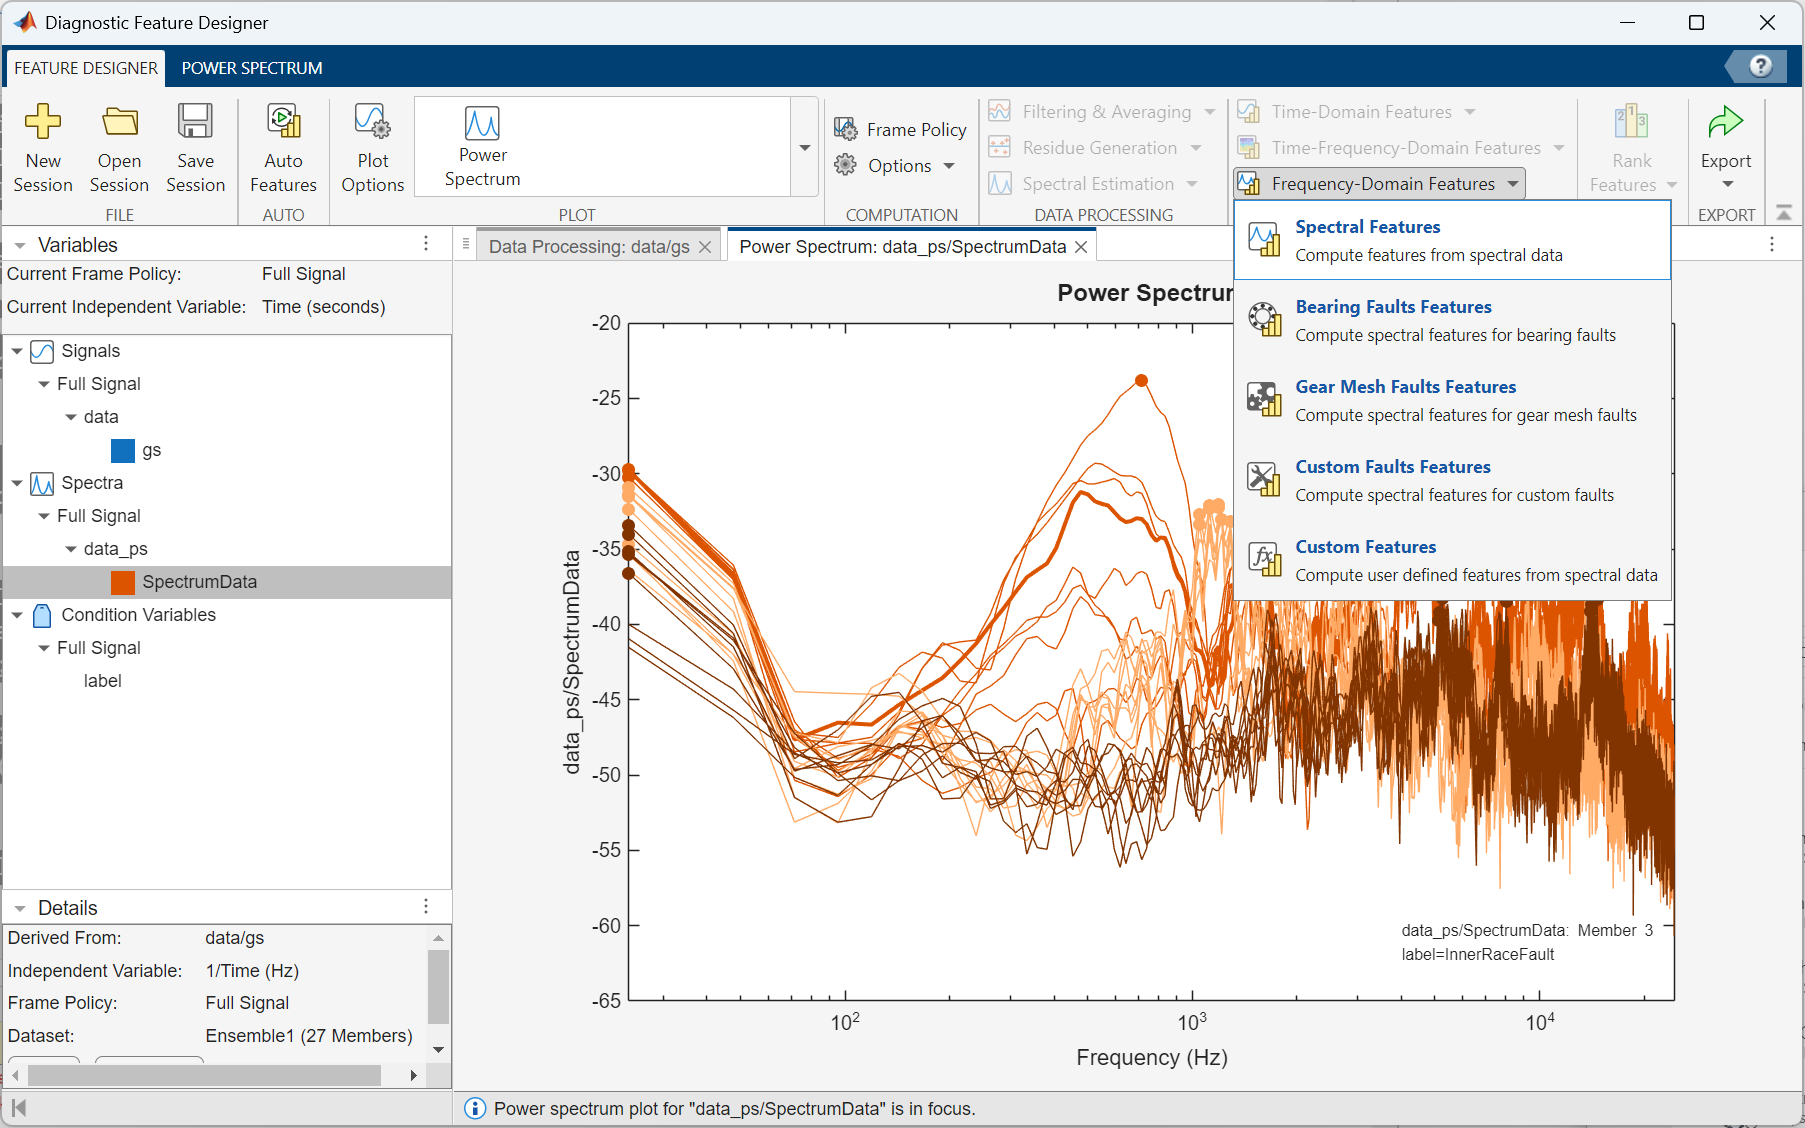

You may noticed that the amplitude, width of the peaks in this spectrum are distinctive between the normal and two abnormal conditions. We will use these features. 

- Change the Number of Peaks to 10 and click Apply. 

- You can find the histogram of the extracted features (the peak amplitude and frequency) for the first 10 peaks in the spectrum.

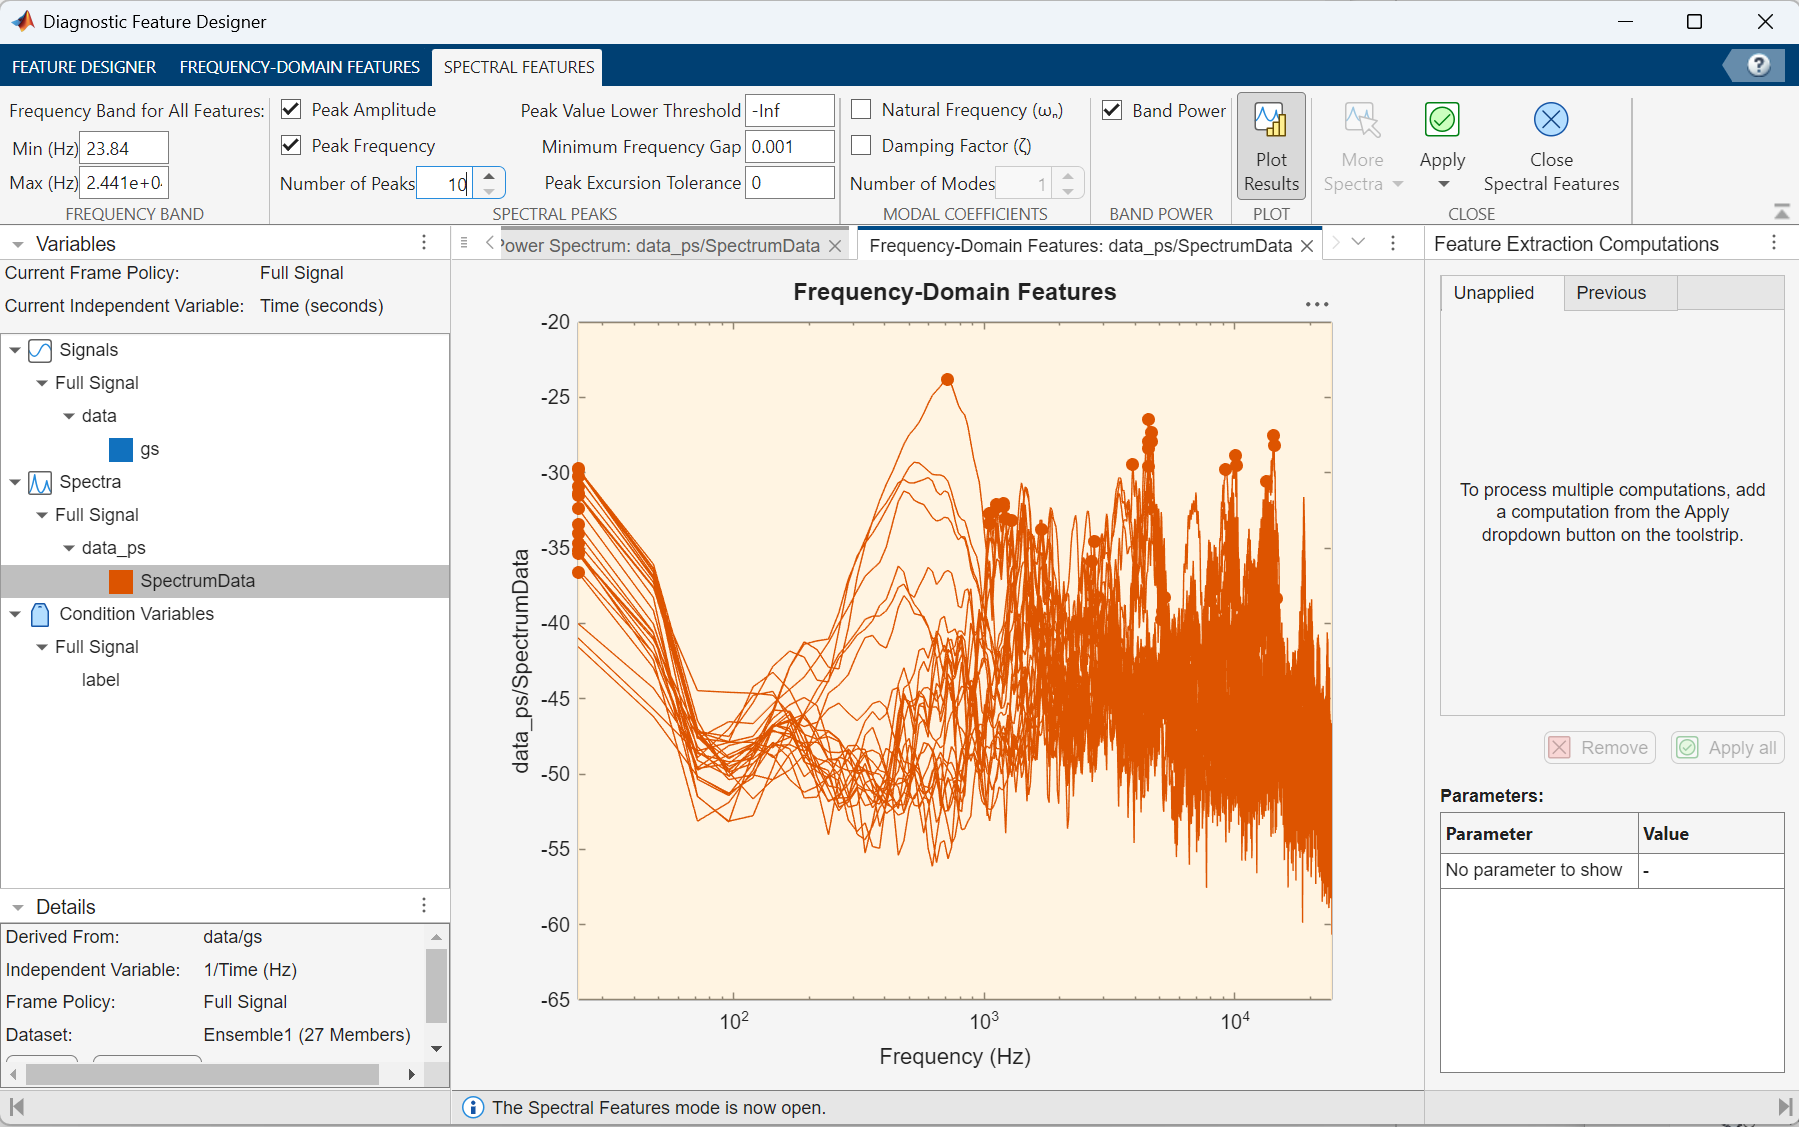

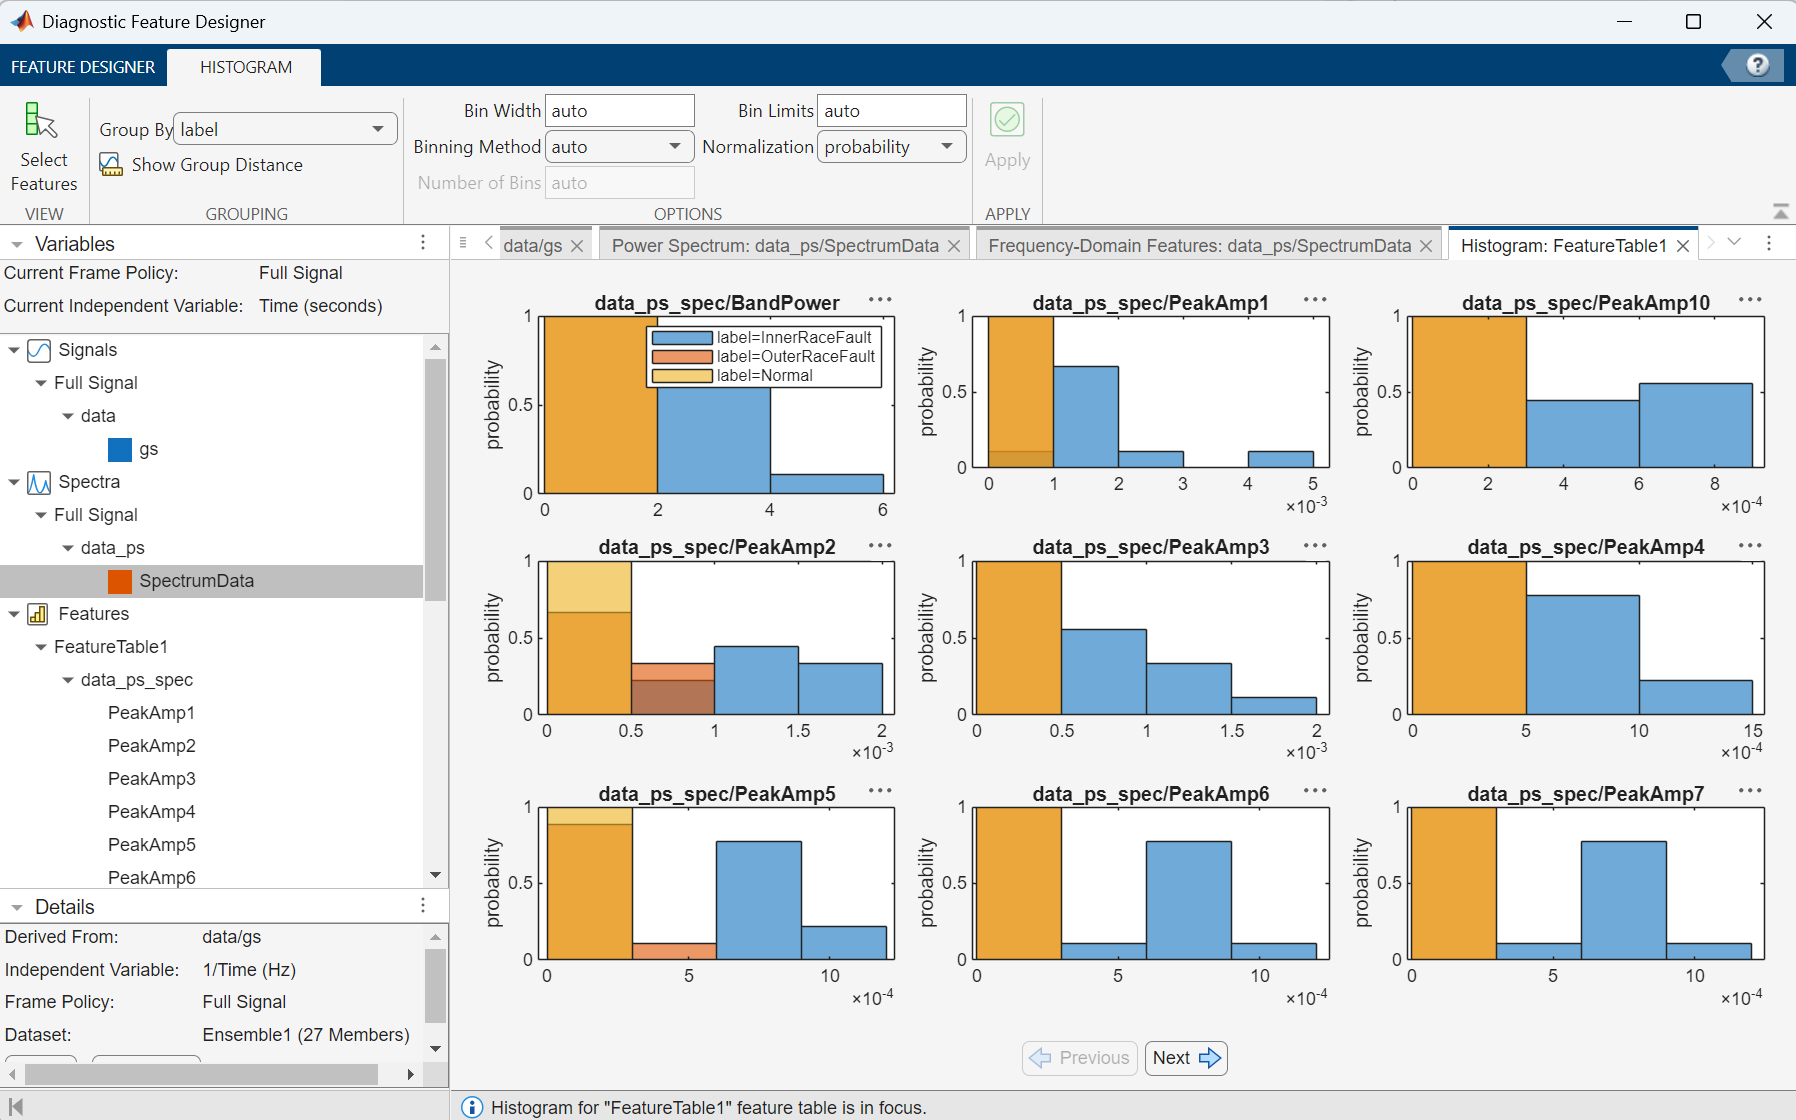

(5) Select Spectral Features from the calculated spectrum. 

- Switch back to FEATURE DESIGNER tab and click Rank Features

- Select FeatureTable1. The default method for chossing the feature is one-way ANOVA, which is generaly helpful in selecting features for machine learning modeling. 

- Chose the top 6 features

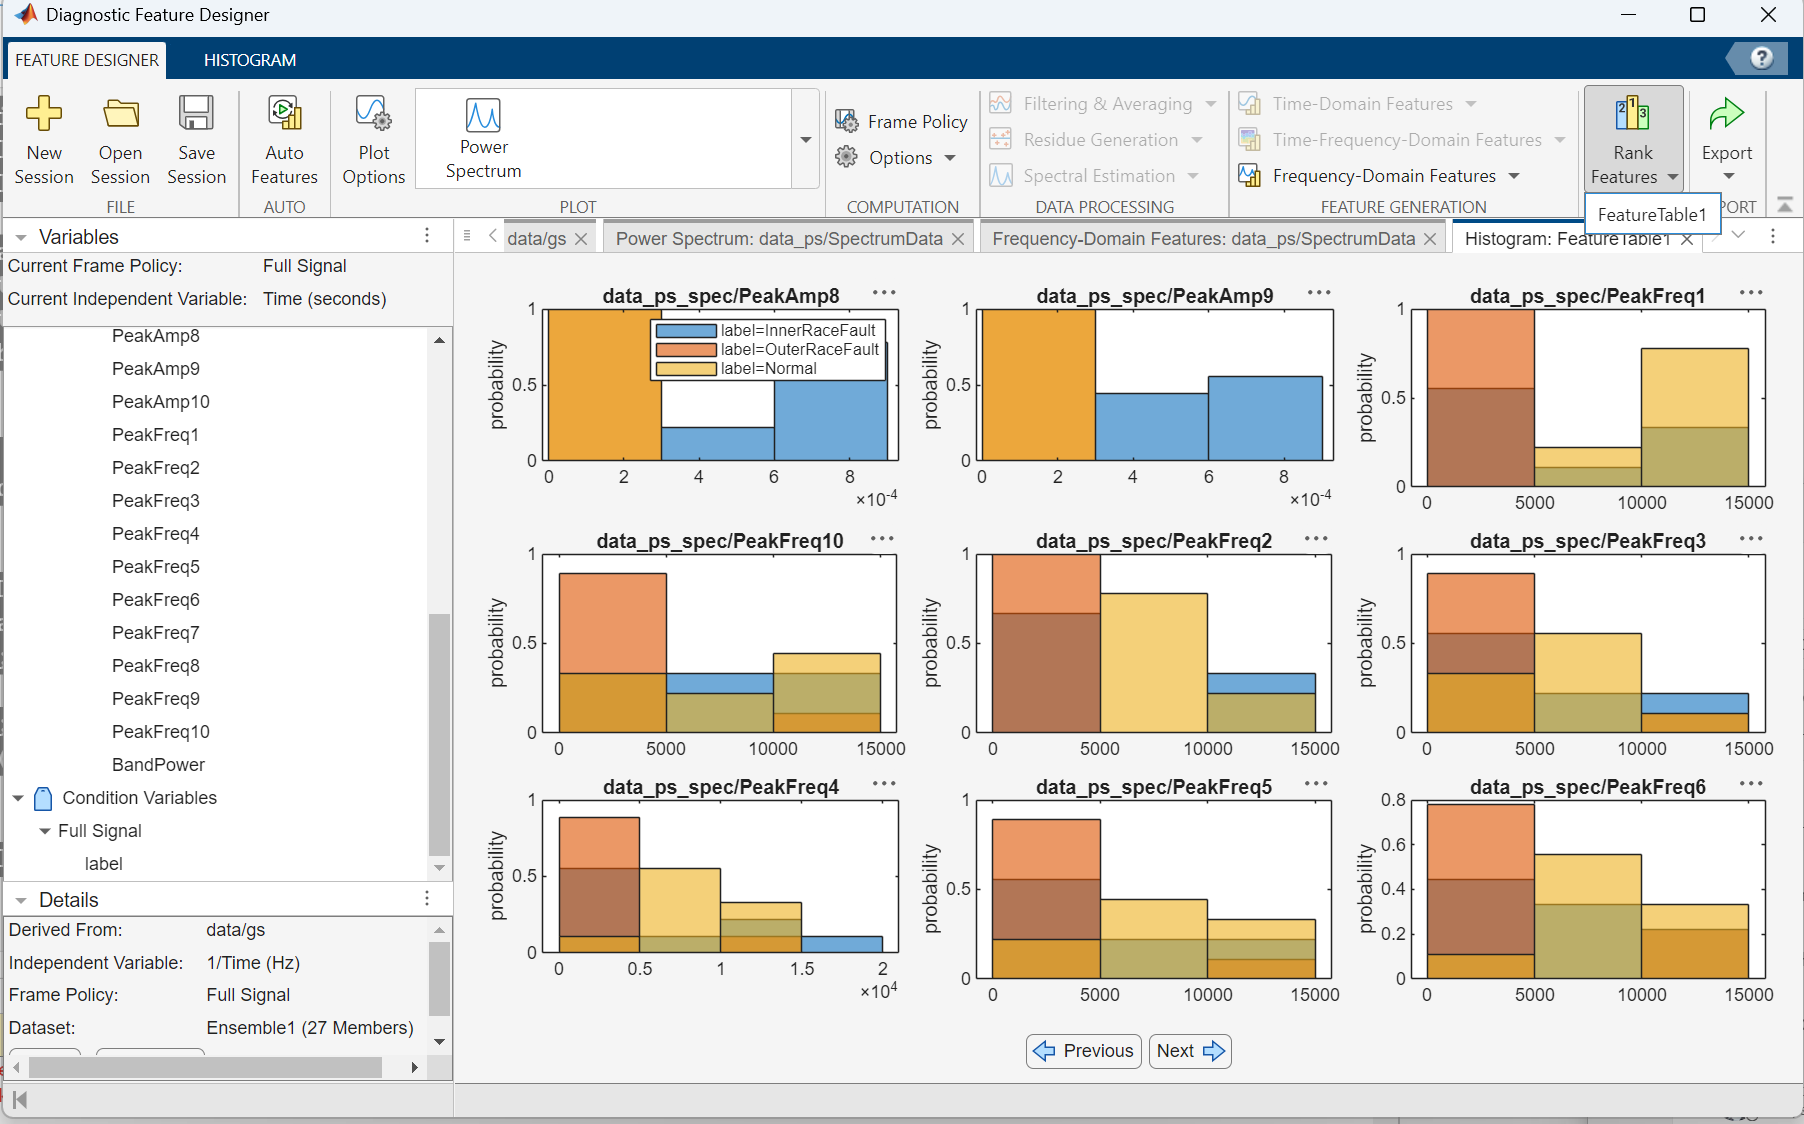

(6) Generate Function for Features. 

- Generate a MATLAB function that takes the same data format and extract the selected features for future use. 

- Choose the top 6 features in the popup window. Now you will have the same function we used for feature extraction for this exercise.

You can also export the features directly to workspace or the Classification/Regression Learner App to train a machine model directly. You can also export it as a simulink block to streamline the feature extraction process in Simulink. 

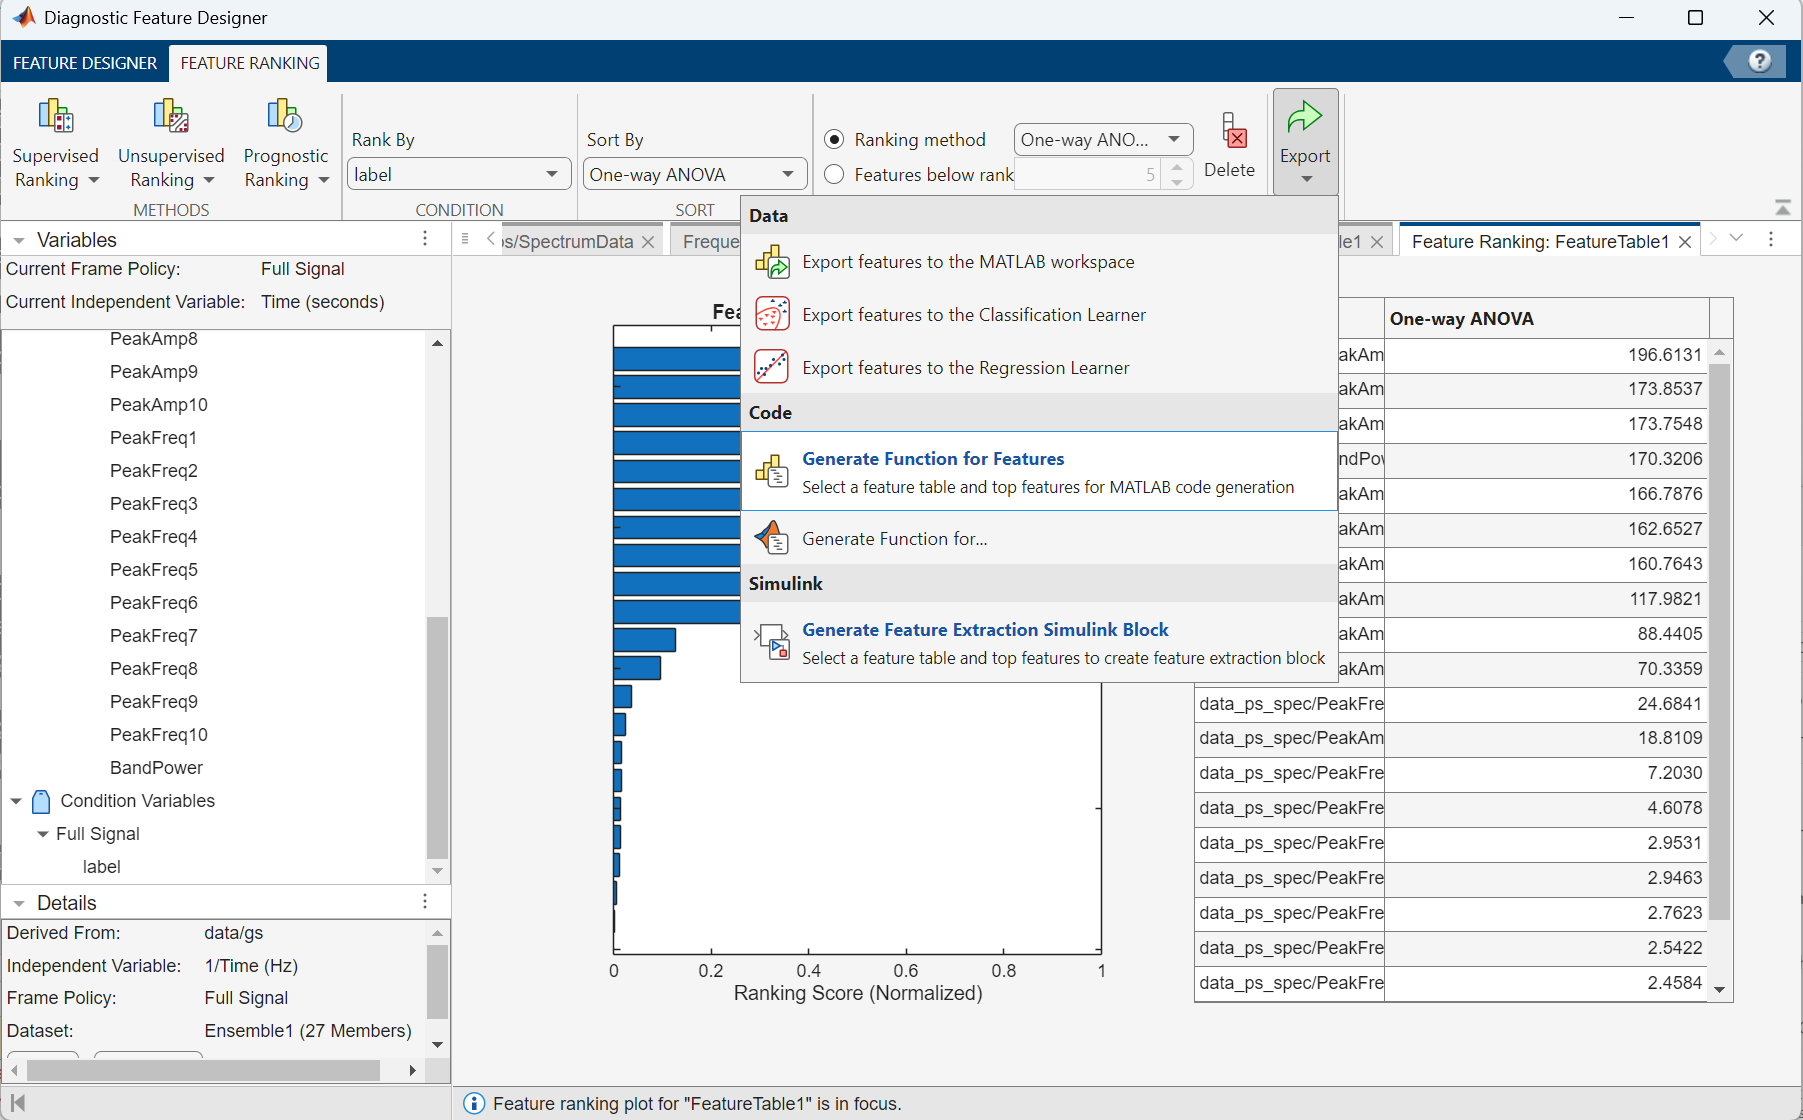

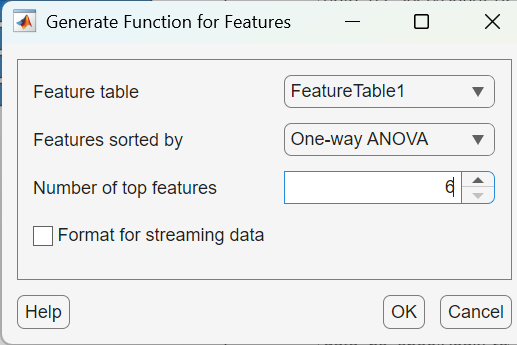

**Helper Function**

function plotRawData(originalData)
labels = string(originalData.label); % Directly access the Label column
unqiqueLabels = unique(labels);
figure;
histogram(categorical(labels, unique(labels)), 'DisplayOrder', 'ascend');
xlabel('Class',Interpreter='none');
ylabel('Count',Interpreter='none');
title('Training Data Labels',Interpreter='none');
grid on;

figure('Name','Raw Data ');tiledlayout(3,1)
numClasses = numel(unqiqueLabels);
for c = 1:numClasses
    nexttile
    TT = originalData.data{1};
    plot(TT.Time,TT.gs);
    xlabel('Time');
    ylabel('Amplitude');
    title(unqiqueLabels(c), 'Interpreter','none');
    grid on;
end
sgtitle('Raw Data Examples for Each Class');
end
